# **Analityczne metody wyznaczania ekstremów. Podstawowe pojęcia optymalizacji.**

clearvars all; close all;

syms x y

fun = x .* exp(-x.^2 - y.^2);
grad = gradient(fun);
hess = hessian(fun);

[x_g, y_g] = solve(grad);

for i = 1:length(x_g)
    h_int = subs(hess, [x, y], [x_g(i), y_g(i)]);
    h_int = (h_int + h_int')/2;
    check_definiteness(h_int, x_g(i), y_g(i))
end

Dodatnio określona dla punktu krytycznego: (-0.707107, 0.000000) 
Minimum lokalne 

Ujemnie określona dla punktu krytycznego: (0.707107, 0.000000) 
Maksimum lokalne 



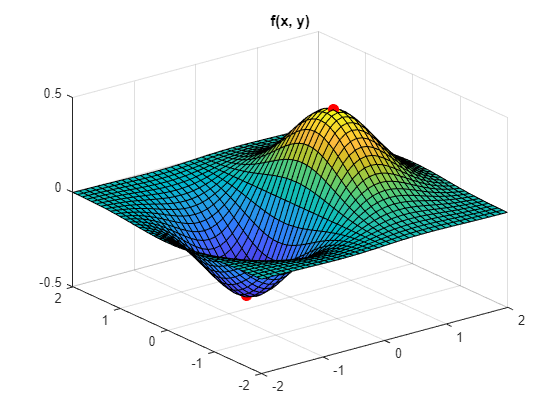


x = -2:0.1:2; y = -2:0.1:2; 
[X,Y] = meshgrid(x,y); 
Z = x.*exp(-X.^2-Y.^2);
fun = matlabFunction(fun);

figure()
surf(X, Y, Z); hold on;

for j = 1:length(x_g)
    plot3(x_g(j), y_g(j), fun(x_g(j), y_g(j)), 'r.', MarkerSize=25);
end

hold off; title("f(x, y)");

clearvars all; close all;

syms x y

fun = 0.3*x+0.1*y+(-3.5+0.5*x.^2+0.5*y.^2).^2+100*x .* exp(-x.^2 - y.^2);
grad = gradient(fun);
hess = hessian(fun);

[x_g, y_g] = vpasolve(grad);

for i = 1:length(x_g)
    h_int = subs(hess, [x, y], [x_g(i), y_g(i)]);
    h_int = (h_int + h_int')/2;
    check_definiteness(h_int, x_g(i), y_g(i))
end

Brak ekstremów

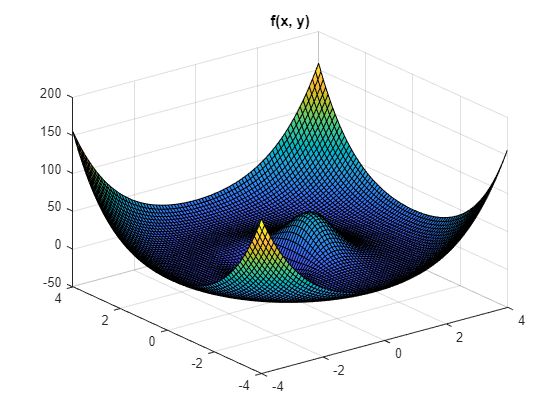


x = -4:0.1:4; y = -4:0.1:4; 

[X,Y] = meshgrid(x,y); 
Z = 0.3*X+0.1*Y+(-3.5+0.5*X.^2+0.5*Y.^2).^2+100*X .* exp(-X.^2 - Y.^2);

figure()
surf(X, Y, Z);
title("f(x, y)");

function [] = check_definiteness(matrix, x, y)
    matrix = eig(matrix);

    if all(matrix < 0)
        fprintf("Ujemnie określona dla punktu krytycznego: " + ...
            "(%f, %f) \nMaksimum lokalne \n\n", x, y);
    elseif all (matrix > 0) 
        fprintf("Dodatnio określona dla punktu krytycznego: " + ...
                "(%f, %f) \nMinimum lokalne \n\n", x, y); 
    else 
        fprintf("Brak ekstremów") 
    end
end
